## Definitions

f = @(z, c) z^2 + c;
c = @(t) [t 1; 0 t];
d = @(t) [t 0; 0 t];
g = @(t) [t 1;0 t];
res = 1000;
ceiling = 10;
iter = 15;

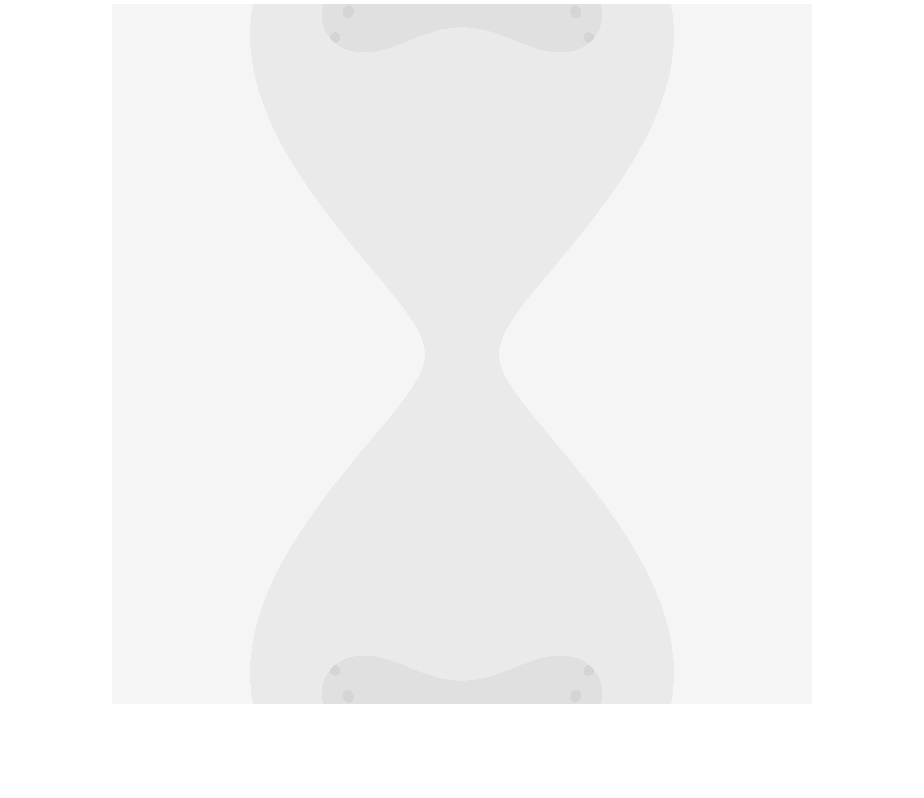

x =   229.4747
  314.7281


y =    63.6387
  129.3321


corners =    -0.1232    0.3884   -1.1182   -0.7240


corners =     0.1741    0.3190   -0.8931   -0.7953


Error using getpts (line 174)
Interruption during mouse point selection.

loops = 10;
frames(loops) = struct('cdata', [], 'colormap',[]);
for j=1:loops
    Norm=matrixIterate(f, g, c(j/5), res, ceiling, iter);
    imshow(Norm)
    drawnow
    frames(j) = getframe;
end

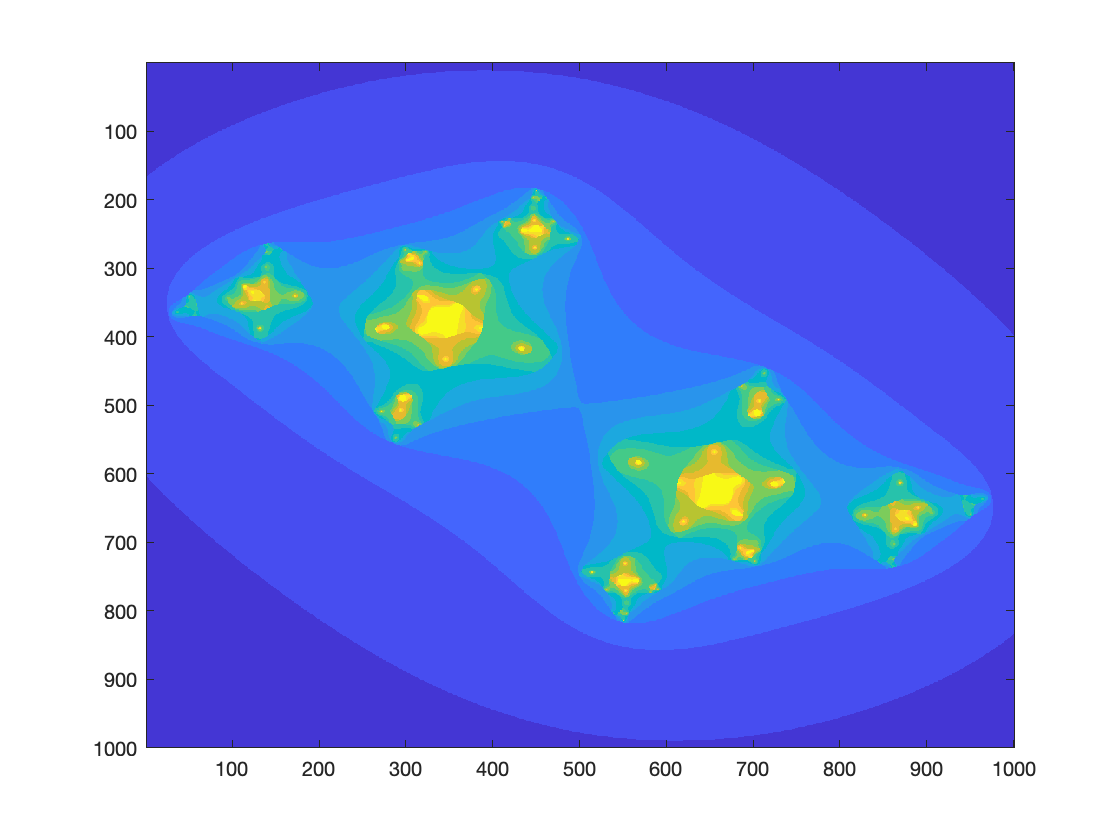

Norm = matrixIterate(f, g, c(t), res, ceiling, iter);
image(Norm)

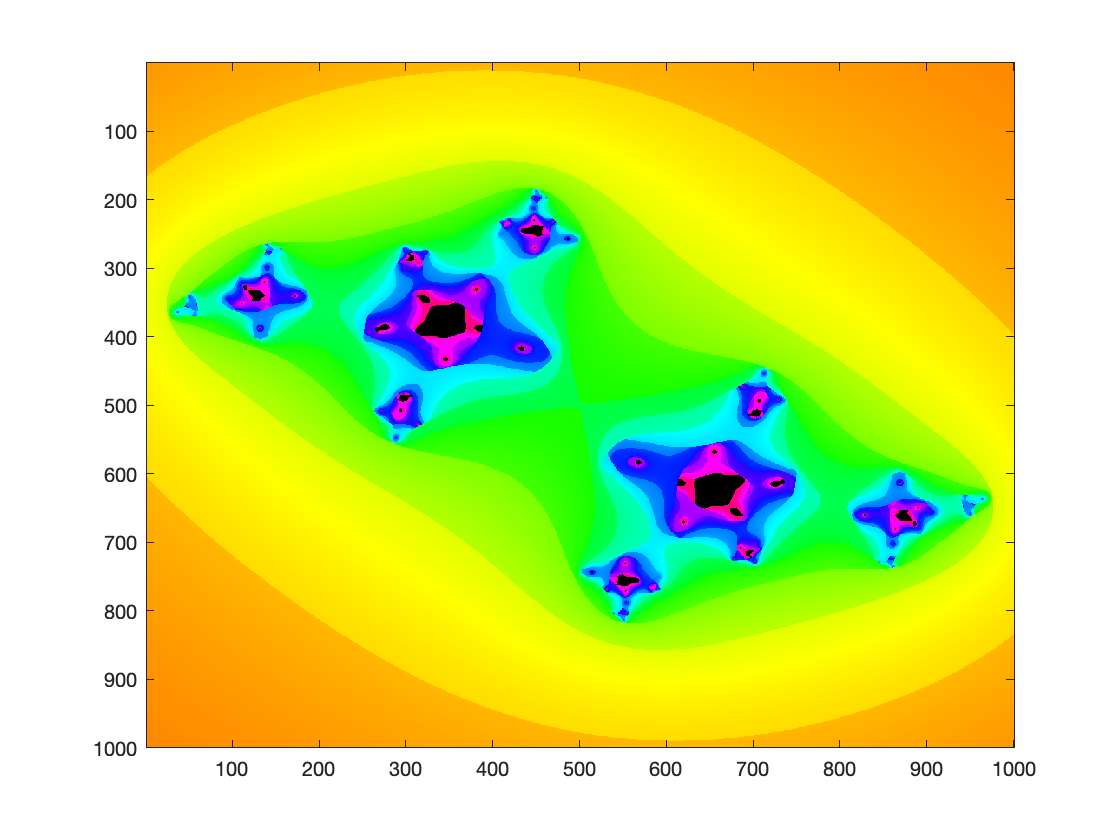

Norm = colorMatrixIterate(f, g, c(t), res, ceiling, iter, [-1.5 1.5 -1.5 1.5]);
image(Norm)

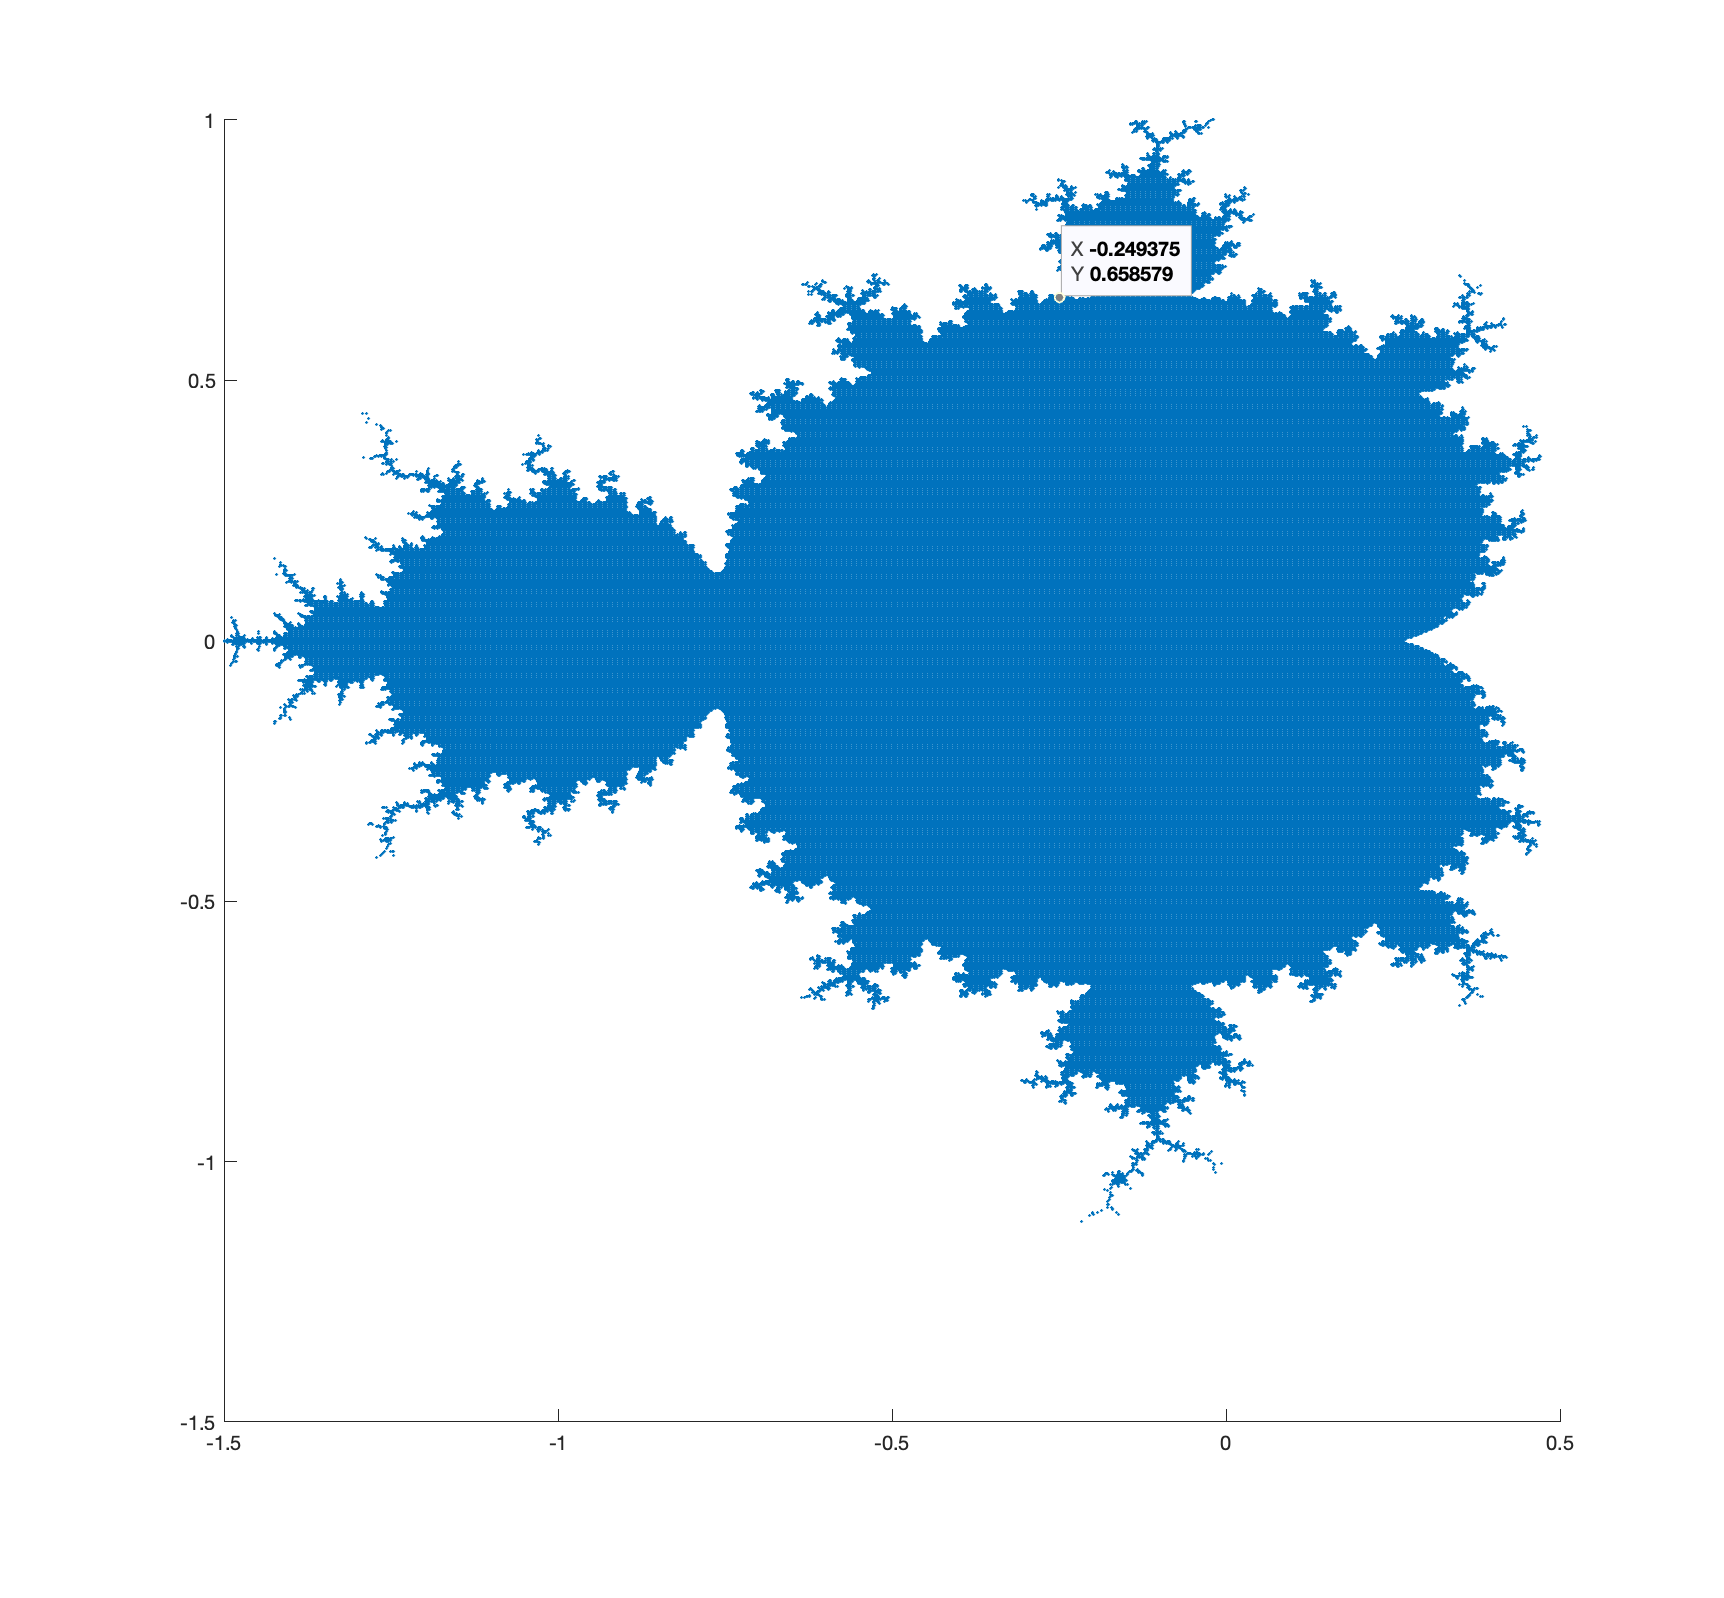

brotSet(f, d, res, ceiling, iter);

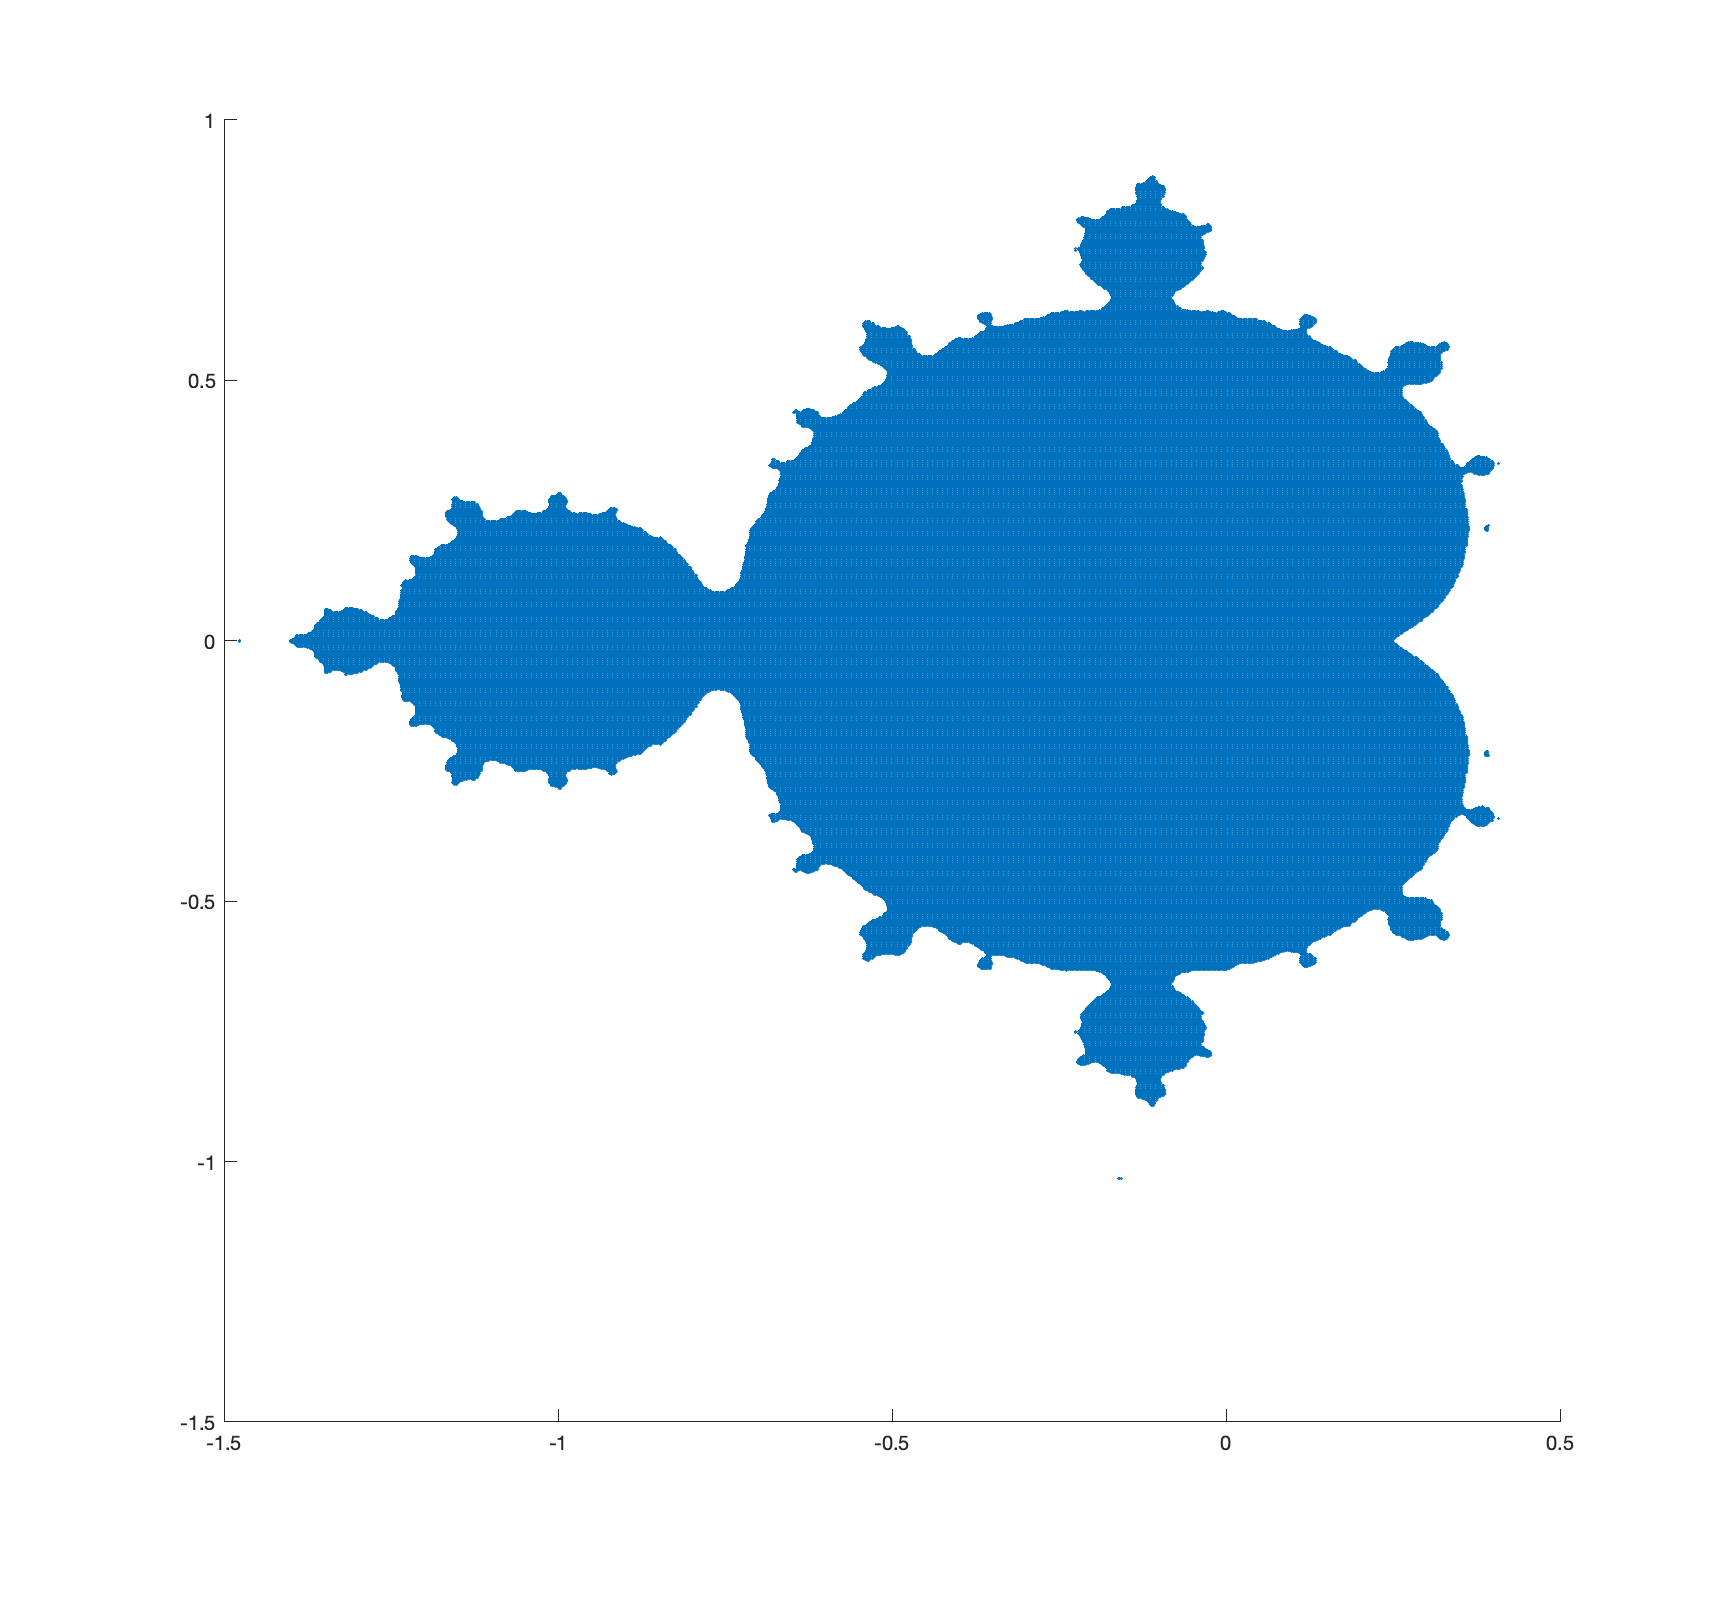

brotSet(f, c, res, ceiling, iter);

function Norm = matrixIterate(f, g, c, res, ceiling, iter)
    x = linspace(-1.5, 1.5, res);
    y = linspace(-1.5, 1.5, res);
    [X, Y] = meshgrid(x,y);
    Z = X + 1i*Y;
    Norm = zeros(res);
    for row=1:res
        for col=1:res
            T = Z(row,col);
            current = f(g(T), c);
            for j = 1:iter
                if norm(current,'fro') > ceiling
                    break
                else
                   current = f(current, c);
                end
                Norm(row,col) = 255 - (255 * (1-j/iter));
            end
        end
    end
end


function brot = matrixMandelbrotQ(f, c, ceiling, iter)
   Zero = zeros(2);
   current = f(Zero,c);
   for i=1:iter
       if norm(current,'fro') > ceiling
           break
       else
           current = f(current, c);
       end
   end
   if i ~= iter
       brot = false;
   else
       brot = true;
   end
end

function brot = brotSet(f, c, res, ceiling, iter)
    x = linspace(-1.5,1,res);
    y = linspace(-1.5,1,res);
    xaxis = [];
    yaxis = [];
    for row=1:res
        for col=1:res
            member = matrixMandelbrotQ(f, c(x(row) + y(col)*1i), ceiling, iter);
            if member
                xaxis = [xaxis x(row)];
                yaxis = [yaxis y(col)];
            end
        end
    end
    scatter(xaxis, yaxis, 3, 'filled')
end